# **POD applied to an image**

*V. Matray*

*Aicha Maaoui*

clear all
close all
clc

## POD by SVD

**load original image**

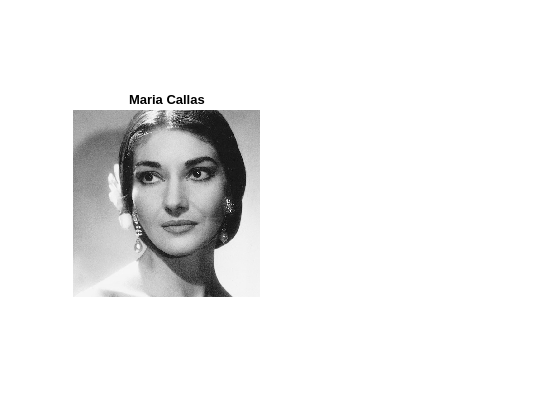

UCimage = imread('callas.jpg');
UCimage = im2double(UCimage(:,:,1));
figure
subplot(1,2,1)
colormap(gray); imagesc(UCimage(:,:));axis equal;axis tight; axis off;
title ('Maria Callas')

**Get dimensions of the image**

n_T = size(UCimage, 1);
n_M = size(UCimage, 2);
M = UCimage;

**SVD on the image**

[U,S,V] = svd(M);

**Order for reconstruction ?**

order = 50; %modes

**Initialize the reconstruction **

M_POD = zeros(n_M,n_T)';

**Reconstruction :**

for o = 1:order
    M_POD = M_POD +S(o,o)*U(:,o)*V(:,o)';
end

**Optional challenge: build M_POD using a single Matlab line **

M_POD = U(:,1:o)*S(1:o,1:o)*V(:,1:o)';

**Plot**

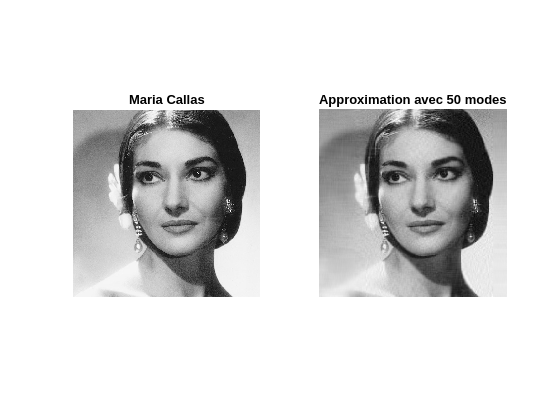

subplot(1,2,2)
colormap(gray); imagesc(M_POD(:,:));axis equal;axis tight; axis off;
title("Approximation avec "+order+" modes")

imwrite(M_POD, 'callas_gray_comp.jpg'); % Save compressed image in file

## Calculation of the reconstruction error

**Plot the reconstruction error as a function of the number of modes used.** The reconstruction error considered here will be calculated with the norm of your choice (you can use the "norm" function of Matlab it's the fastest/ easiest way ;) ). 

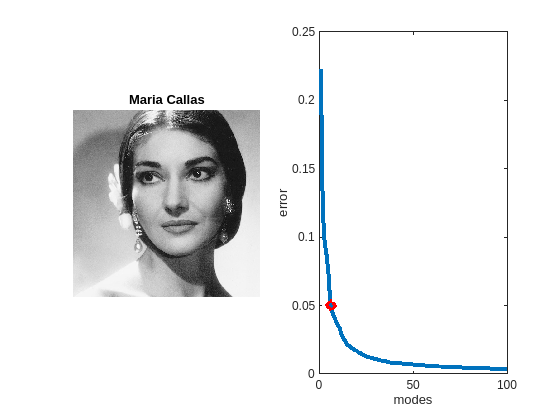

err =[];
N_modes = 100;
for n= 1:N_modes
        M_POD = U(:,1:n)*S(1:n,1:n)*V(:,1:n)';
        e = norm(M-M_POD)/norm(M);
        err = [err,e];
end

% Plotting of the error
x = 1:N_modes;
y_proj = 0.05;
[~,y_index] = min(abs(err-y_proj));
x_proj = x(y_index);

plot(1:N_modes,err,x_proj,y_proj, 'ro', 'LineWidth', 3)
xlabel('modes')
ylabel('error')

% modes for an error = 0.05
x=1:N_modes;
x_value = round(interp1(err, x, 0.05))

x_value = 6

% An appropriate number of modes 6 is achived for an error equal to 0.05 